# Lab 5- Bar Yerushalmian and Ben Efrat

clear , clc;

## part 1

%%%1
I = zeros(41);
I(1:5,1:5) = 255;
I = logical(I);

%%%2
FFT1 = fft2(I);
FFT1_Shift = fftshift(FFT1);


fi=figure()

fi =   Figure (42) with properties:

      Number: 42
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


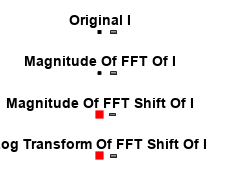

subplot(4,1,1)
imshow(I)
title("Original I");
colorbar
hold on;
plot(0,0, 'r+', 'MarkerSize', 5, 'LineWidth', 5);

subplot(4,1,2)
imshow(abs(FFT1),[])
colorbar
title("Magnitude Of FFT Of I")
hold on;
plot(0,0, 'r+', 'MarkerSize', 5, 'LineWidth', 5);

subplot(4,1,3)
imshow(abs(FFT1_Shift),[])
title("Magnitude Of FFT Shift Of I")
colorbar
hold on;
plot(21,21, 'r+', 'MarkerSize', 5, 'LineWidth', 5);

subplot(4,1,4)
imshow(log(abs(FFT1_Shift)),[])
title("Log Transform Of FFT Shift Of I")
colorbar
hold on;
plot(21,21, 'r+', 'MarkerSize', 5, 'LineWidth', 5);
saveas(fi,"0FFT1_fig",'jpg');

%%%3
CircShiftI = circshift(I,[-2 -2]);
%imshow(CircShiftI)
FFT2 = fft2(CircShiftI);
FFT2_Shift = fftshift(FFT2);


fi=figure()

fi =   Figure (43) with properties:

      Number: 43
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


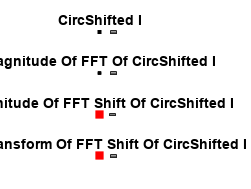

subplot(4,1,1)
imshow(CircShiftI)
title("CircShifted I");
colorbar
hold on;
plot(0,0, 'r+', 'MarkerSize', 5, 'LineWidth', 5);

subplot(4,1,2)
imshow(abs(FFT2),[])
colorbar
title("Magnitude Of FFT Of CircShifted I")
hold on;
plot(0,0, 'r+', 'MarkerSize', 5, 'LineWidth', 5);

subplot(4,1,3)
imshow(abs(FFT2_Shift),[])
title("Magnitude Of FFT Shift Of CircShifted I")
colorbar
hold on;
plot(21,21, 'r+', 'MarkerSize', 5, 'LineWidth', 5);

subplot(4,1,4)
imshow(log(abs(FFT2_Shift)),[])
title("Log Transform Of FFT Shift Of CircShifted I")
colorbar
hold on;
plot(21,21, 'r+', 'MarkerSize', 5, 'LineWidth', 5);
saveas(fi,"1FFT2_fig",'jpg');

%%%4
fi=figure()

fi =   Figure (44) with properties:

      Number: 44
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


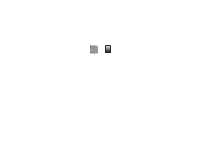

diff = abs(FFT2)-abs(FFT1); % Theres no difference between the two ffts because shifting affects only phase.
imshow(diff,[]);  
colorbar
saveas(fi,"2diff_fig",'jpg');


fi=figure()

fi =   Figure (45) with properties:

      Number: 45
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


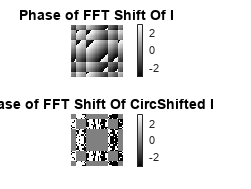

subplot(2,1,1)
imshow(angle(FFT1_Shift),[]); % Linear Phase 
title("Phase of FFT Shift Of I");
colorbar
subplot(2,1,2)
imshow(angle(FFT2_Shift),[]);
title("Phase of FFT Shift Of CircShifted I"); % Zero Phase 
colorbar
saveas(fi,"3phase_fig",'jpg');


%%%5

I = zeros(40);
I(1:5,1:5) = 255;
I = logical(I);

FFT3 = fft2(I);
FFT3_Shift = fftshift(FFT3);


fi=figure()

fi =   Figure (46) with properties:

      Number: 46
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


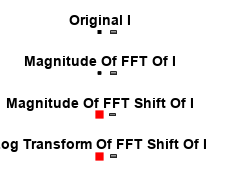

subplot(4,1,1)
imshow(I)
title("Original I");
colorbar
hold on;
plot(0,0, 'r+', 'MarkerSize', 5, 'LineWidth', 5);

subplot(4,1,2)
imshow(abs(FFT3),[])
colorbar
title("Magnitude Of FFT Of I");
hold on;
plot(0,0, 'r+', 'MarkerSize', 5, 'LineWidth', 5);

subplot(4,1,3)
imshow(abs(FFT3_Shift),[])
title("Magnitude Of FFT Shift Of I");
colorbar
hold on;
plot(21,21, 'r+', 'MarkerSize', 5, 'LineWidth', 5);

subplot(4,1,4)
imshow(log(abs(FFT3_Shift)),[])
title("Log Transform Of FFT Shift Of I");
colorbar
hold on;
plot(21,21, 'r+', 'MarkerSize', 5, 'LineWidth', 5);
saveas(fi,"4FFT3_fig",'jpg');



%%%6

% Create IV 
I = zeros(41);
I(1,1:5) = 255;
IV = logical(I);

% Create IH
I = zeros(41);
I(1:5,1) = 255;
IH = logical(I);

%%%7+8
%FFT IH
FyIh = fft(IH);
FyIh = fftshift(FyIh);

%FFT IV
FxIv = fft(IV');
FxIv = FxIv';
FxIv = fftshift(FxIv);

%PLOTTING IH
fi=figure()

fi =   Figure (47) with properties:

      Number: 47
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


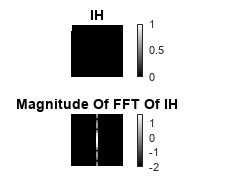

subplot(2,1,1)
imshow(IH)
title("IH");
colorbar

subplot(2,1,2)
imshow(log(abs(FyIh)),[])
colorbar
title("Magnitude Of FFT Of IH")

saveas(fi,"5IH_fig",'jpg');


%PLOTTING IV

fi=figure()

fi =   Figure (48) with properties:

      Number: 48
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


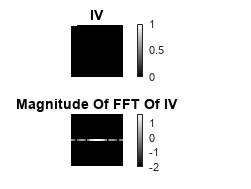

subplot(2,1,1)
imshow(IV)
title("IV");
colorbar

subplot(2,1,2)
imshow(log(abs(FxIv)),[])
colorbar
title("Magnitude Of FFT Of IV")
saveas(fi,"6IV_fig",'jpg');


%%%9
Res = IH*IV;
fi=figure()

fi =   Figure (49) with properties:

      Number: 49
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


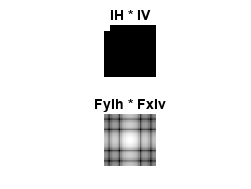

subplot(2,1,1)
imshow(Res,[])
title("IH * IV")

Fourier_Transorm_Res = FyIh*FxIv;
subplot(2,1,2)
imshow(log(abs(Fourier_Transorm_Res)),[])
title("FyIh * FxIv")
saveas(fi,"7multiply_fig",'jpg');

## part 2


clear , clc 

eps = 0.001;


load lab5.mat vn1

[x,y] = size(vn1);

zeroM = zeros(x,y);

% making original cross
cross = zeros(x,y);

cross(26:36,34:36) = 255;
cross(30:32,30:40) = 255;


% blurred cross
g = imcrop(vn1,[26 26 18 10]);
zeroM(26:36,26:44) = g; % blurred cross image

% degradation function finding
F_cross = fft2(cross); %% fft of original cross
F_g = fft2(zeroM); % fft of blurred cross
F_vn1 = fft2(vn1); % fft of blurred image


H = F_g./F_cross;

[x2,y2]=size(H);

%restore filter

for i = 1:x2
    for j = 1:y2

        if(abs(H(i,j)) > eps) % check if denominator is 0

        R(i,j) = 1/H(i,j);

           else
           R(i,j) = 0;
    

        end
 
    end
end


% multiply blurred image with restoration filter

F_img_new = F_vn1.*R;

img_new = ifft2(F_img_new);
figure(9)
subplot(231)
imshow(vn1,[]);
title("Original Blurred Image")
subplot(232)
imshow(img_new,[]);
title("Unblurred Image")
subplot(233)
imshow(abs(H),[])
title("Degradation Filter (H)")

subplot(234)
h = ifft(H);
imshow(h,[])

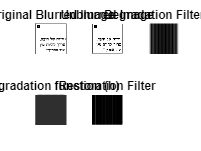

title("Degradation function (h)")

subplot(235)
imshow(abs(R),[])
title("Restoration Filter")